# FEA Analysis of TArm Design

% This section basically pulls the CAD file, sets  the analysis to static,
% and generate a mesh plus face labels visual.
tArmGm = fegeometry("TArmCAD.stl"); 
tArmGm = scale(tArmGm, 0.001); % converts units into meters
tArmMd = femodel(AnalysisType="structuralStatic",Geometry=tArmGm);
tArmMd = generateMesh(tArmMd); % generate a mesh of the geometry
%pdemesh(tArmMd); % visualize the mesh
%pdegplot(tArmMd,FaceLabels="on",FaceAlpha=0.3);

% This section assigns the material properties for the drone arm. We can
% loop it to see the material properties for the 6 materials we were given
feaResults = table();

for m = 1:numel(materials)
mat = materials(m);
tArmMd.MaterialProperties = materialProperties(PoissonsRatio = mat.nu, YoungsModulus= mat.E_Pa, MassDensity= mat.rho_kg_m3);

tArmMd.FaceBC(5) = faceBC(Constraint="fixed"); %makes drone mount fixed
tArmMd.CellLoad = cellLoad(Gravity=[0 0 -g]); %makes drone arm experience gravity
motorWeight = 0.105 * g;
thrustForce = thrustMotor * g;
netForce = thrustForce - motorWeight;
tArmMd.FaceLoad(13) = faceLoad(SurfaceTraction = [0 0 (netForce/0.000424115)]); %makes the drone arm experience thrust from motor

sol = solve(tArmMd); % completes the FEA

maxStress = max(sol.VonMisesStress);
maxDisplacement = max(sol.Displacement.Magnitude);
factorOfSafety = mat.yieldStrength_Pa/maxStress; %checks Factor of Safety

feaResults = [feaResults; table(string(mat.name), maxStress, maxDisplacement, factorOfSafety, 'VariableNames', {'Material', 'MaxStress','MaxDisplacement (Z)','FactorOfSafety'})];
end



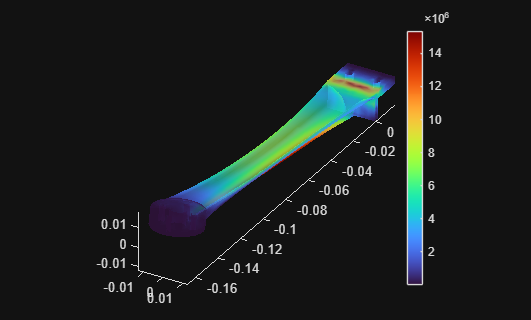

% Data to visualize
meshData = sol.Mesh;
nodalData = sol.VonMisesStress;
deformationData = sol.Displacement;

% Create PDE result visualization
resultViz2 = pdeviz(meshData,nodalData, ...
    "DeformationData",deformationData, ...
    "DeformationScaleFactor",4.5882, ...
    "ColorLimits",[4609 15350000], ...
    "Transparency",0.61);


% Clear temporary variables
clearvars meshData nodalData deformationData